
clear;clc;close all;
set(0,'defaultlinelinewidth',3)
set(0,'defaultaxeslinewidth',2);
set(0,'defaultaxesfontsize',28);
set(0,'defaulttextfontsize',28);
set(0,'DefaultLineMarkerSize',28);
set(0,'Defaultaxesfontname','Times New Roman');
% addpath('./circleData');

% figure(); box on;
% plot(x/D,U0_axi,'-');
% xlabel('$x/D$','interpreter','latex');
% ylabel('$U_0$','interpreter','latex');
% set(gcf,'unit','centimeters','position',[20 20 20 20])

% saveas(gcf,'Re_80_U0_axi','epsc')

maxnub = 10000;

positive = 0;
negative = 0;

for i = 1:5000
    x=(randi(maxnub) - 1) / maxnub;
    if x >= 0.5
        positive = positive + 1;
    else
        negative = negative + 1;
    end
    posib_p(i) = positive / i;
    posib_n(i) = negative / i;
end

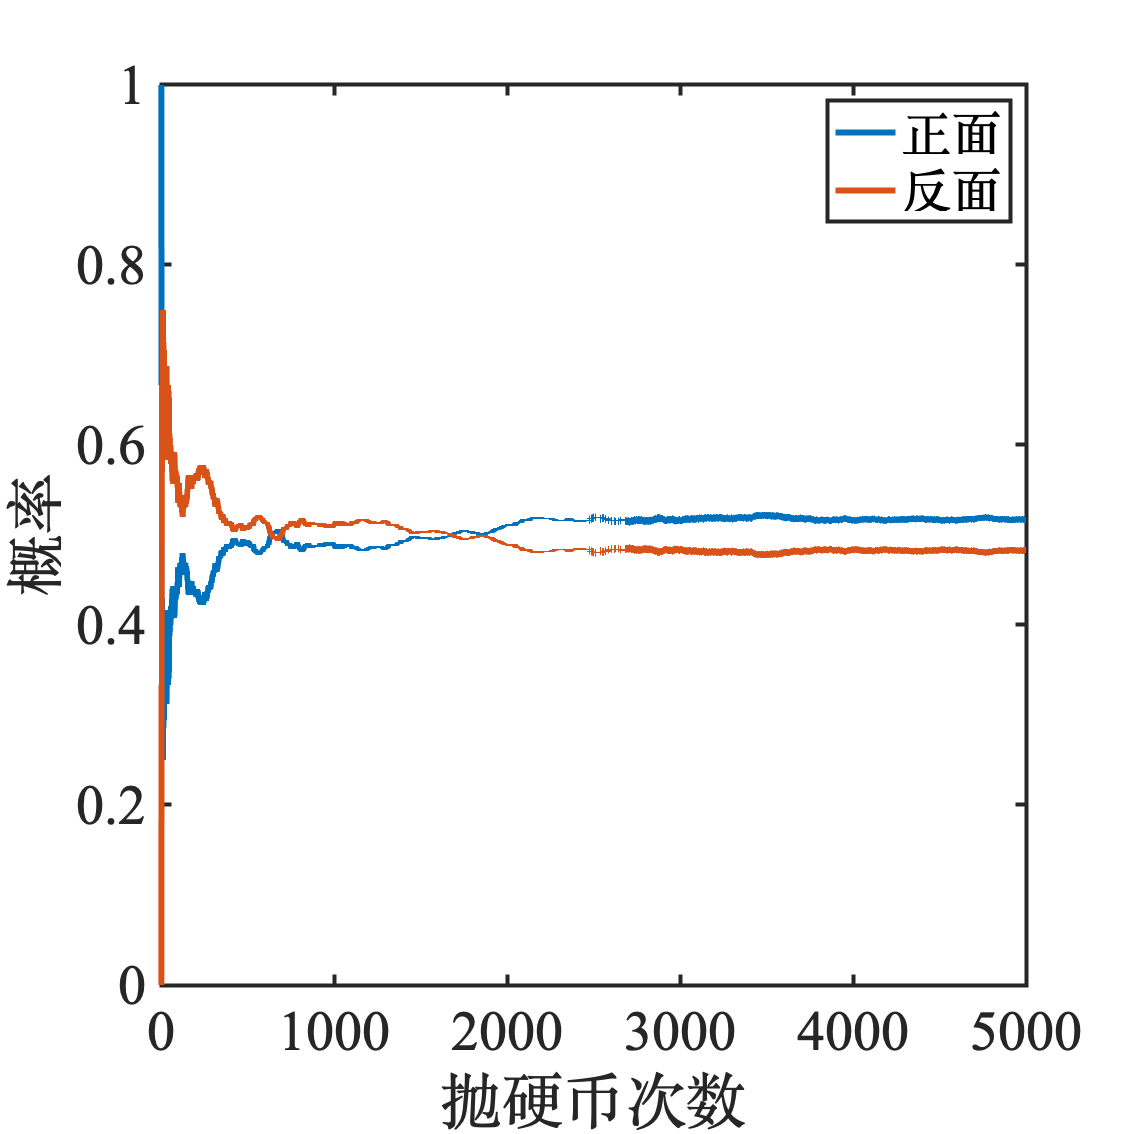


figure(); box on;
plot(posib_p);
hold on;
plot(posib_n);
xlabel('抛硬币次数');
ylabel('概率');
xlim([0 5000])
set(gcf,'unit','centimeters','position',[20 20 20 20])
legend('正面','反面')
hold off;
saveas(gcf,'posi1','epsc')

im = 714025;
ia = 4096;
ic = 150889;

jran = 4380;
positive = 0;
negative = 0;

for i = 1:5000
    jran= mod(jran*ia+ic, im);
    ran= jran / im;
    if ran >= 0.5
        positive = positive + 1;
    else
        negative = negative + 1;
    end
    posib_p(i) = positive / i;
    posib_n(i) = negative / i;
end



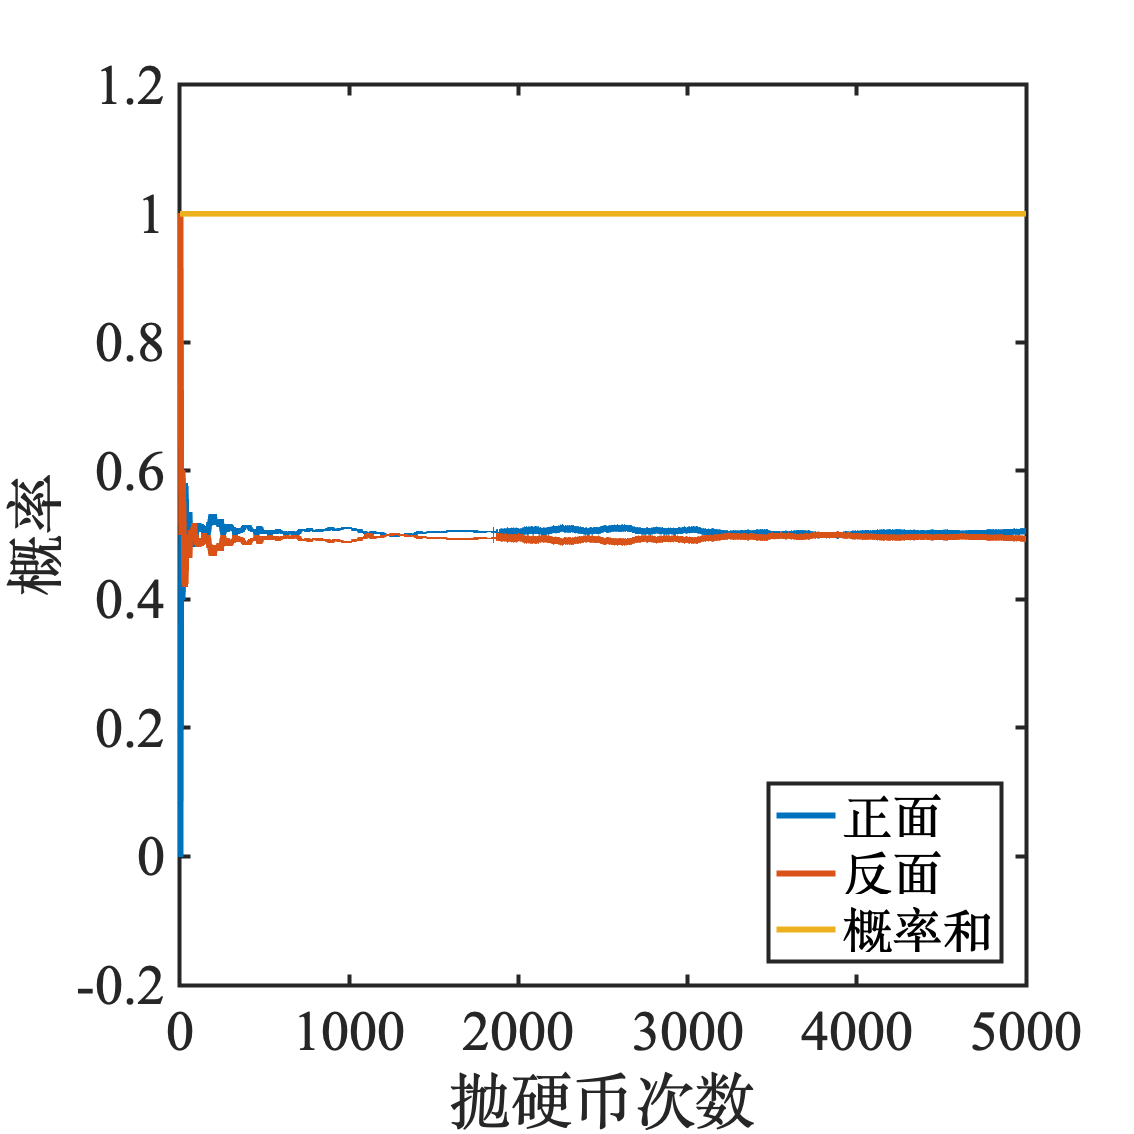


figure(); box on;
plot(posib_p);
hold on;
plot(posib_n);
plot(posib_p+posib_n);
xlabel('抛硬币次数');
ylabel('概率');
xlim([0 5000])
ylim([-0.2 1.2])
set(gcf,'unit','centimeters','position',[20 20 20 20])
legend('正面','反面','概率和',"Location","best")
hold off;
saveas(gcf,'posi2','epsc')

im = 714025;
ia = 4096;
ic = 150889;

jran1 = 4380;
pp = 0;
nn = 0;
pn = 0;

jran2 = 35654;
positive2 = 0;
negative2 = 0;

for i = 1:5000
    jran1 = mod(jran1*ia+ic, im);
    jran2= mod(jran2*ia+ic, im);
    ran1 = jran1 / im;
    ran2 = jran2 / im;
    if ran1 >= 0.5 && ran2 >= 0.5
        pp = pp + 1;
    elseif ran1 < 0.5 && ran2 < 0.5
        nn = nn + 1;
    else
        pn = pn + 1;
    end
    posib_pp(i) = pp / i;
    posib_nn(i) = nn / i;
    posib_pn(i) = pn / i;
end

    
    

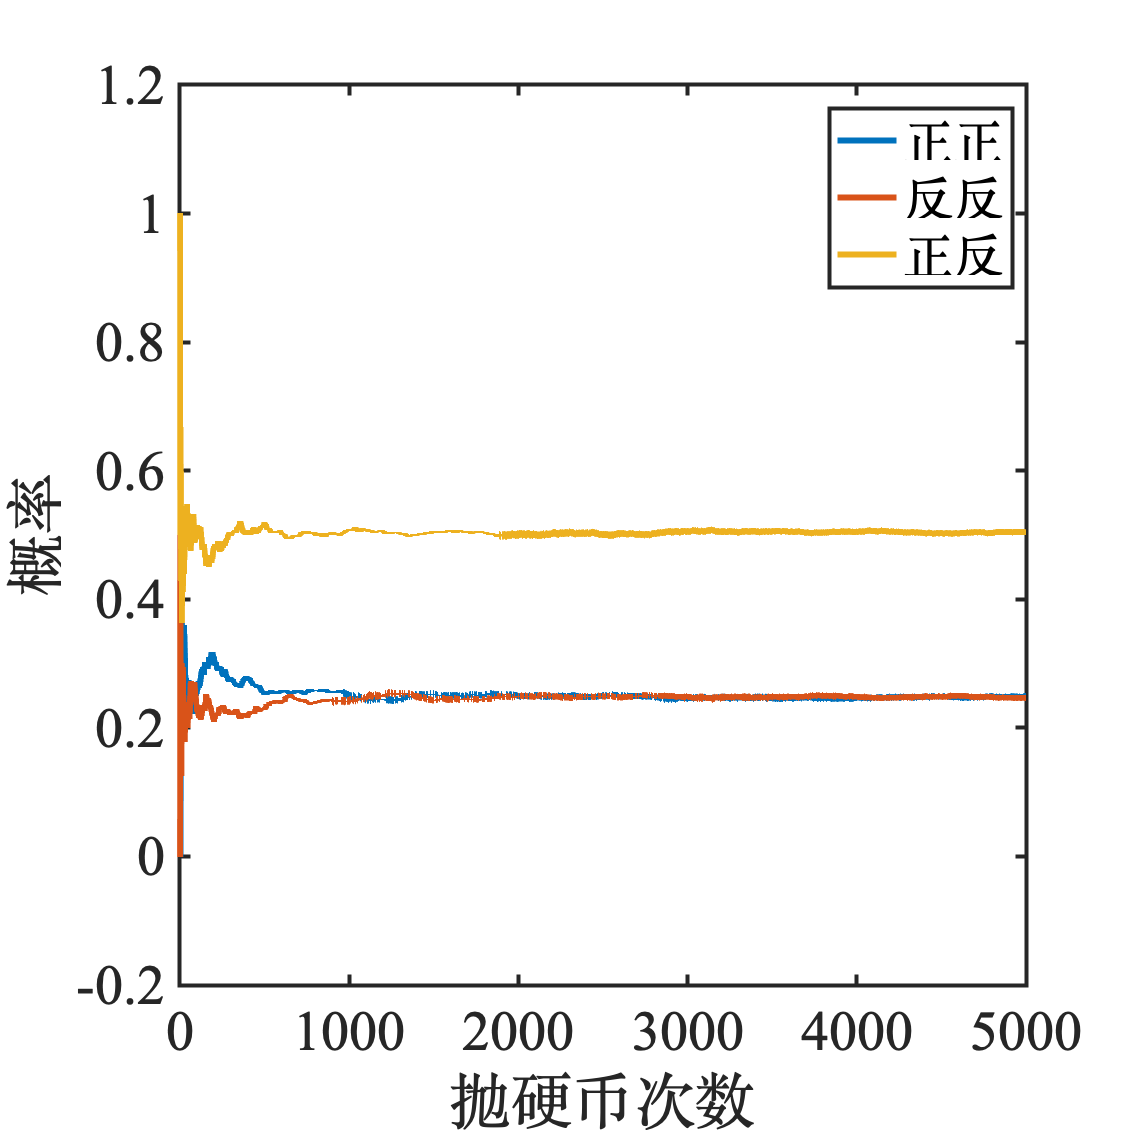

    
figure(); box on;
plot(posib_pp);
hold on;
plot(posib_nn);
plot(posib_pn);
xlabel('抛硬币次数');
ylabel('概率');
xlim([0 5000])
ylim([-0.2 1.2])
set(gcf,'unit','centimeters','position',[20 20 20 20])
legend('正正','反反','正反',"Location","best")
hold off;
saveas(gcf,'posi3','epsc')

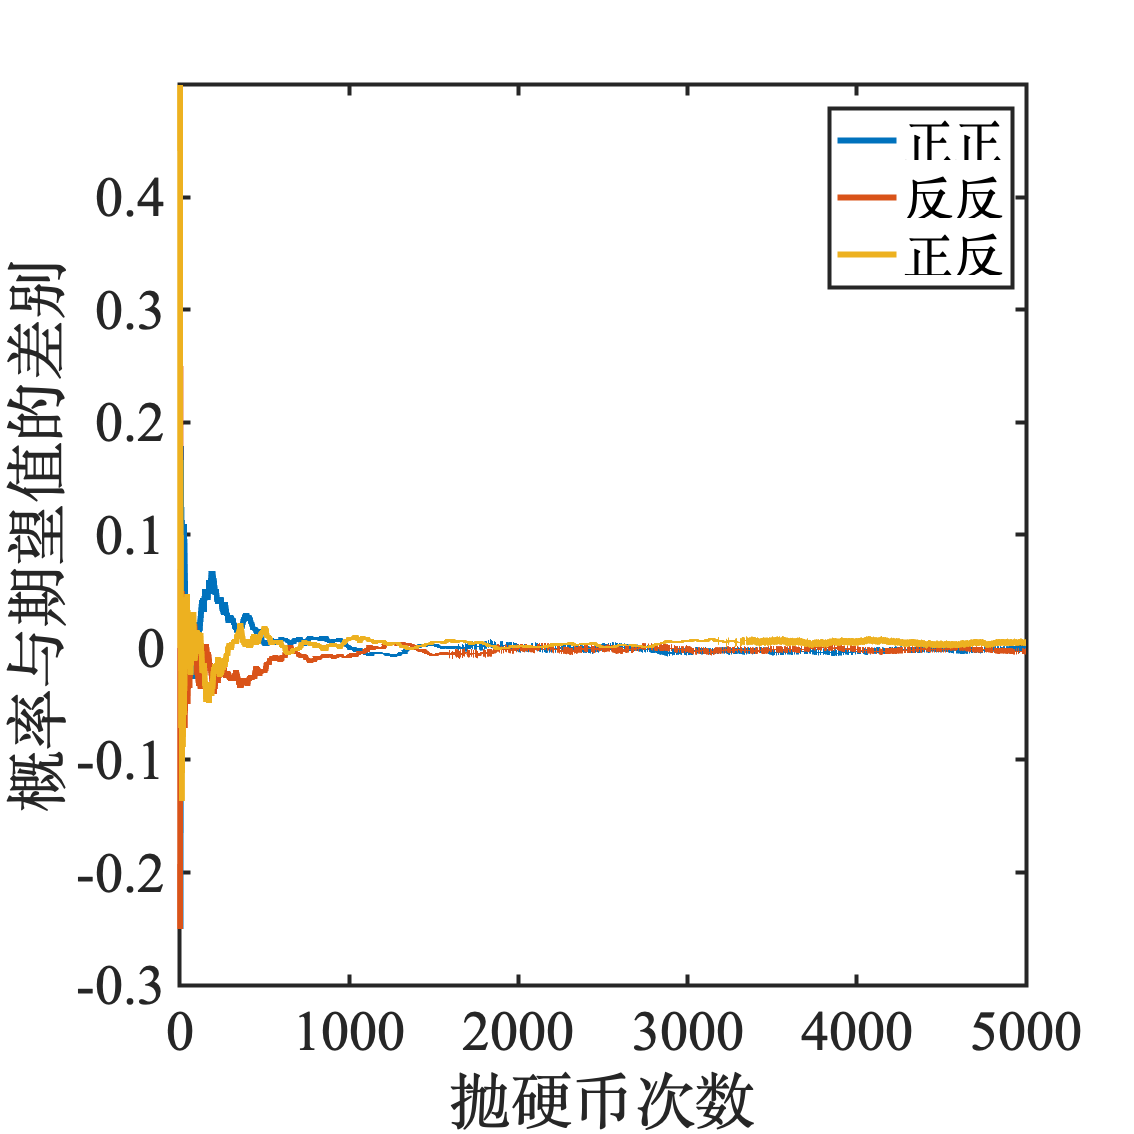

    
figure(); box on;
plot(posib_pp-1/4);
hold on;
plot(posib_nn-1/4);
plot(posib_pn-1/2);
xlabel('抛硬币次数');
ylabel('概率与期望值的差别');
xlim([0 5000])
% ylim([-0.2 1.2])
set(gcf,'unit','centimeters','position',[20 20 20 20])
legend('正正','反反','正反',"Location","best")
hold off;
saveas(gcf,'posi4','epsc')